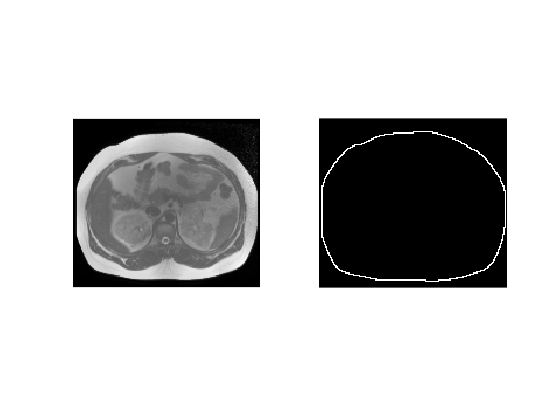

%Load the dataset and show the images with their segmentations
data1 = load("dataForNN_foreBorder_clip0.mat");
data2 = load("dataForNN_foreBorder_clip1.mat");
data3 = load("dataForNN_inside_clip0.mat");

figure();
subplot(1, 2, 1), imshow(data1.trainingImage);
subplot(1, 2, 2), imshow(data1.trainingSegmentation);

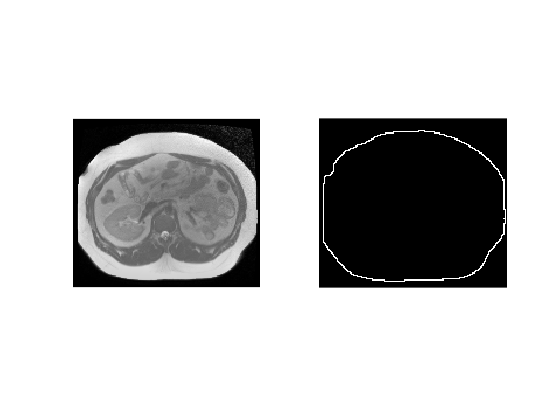


figure();
subplot(1, 2, 1), imshow(data1.testImage, []);
subplot(1, 2, 2), imshow(data1.testSegmentation, []);

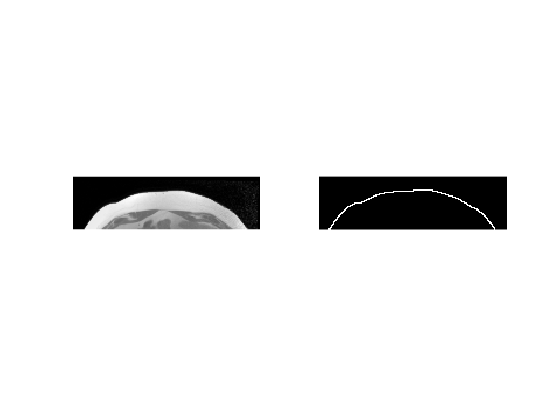



figure();
subplot(1, 2, 1), imshow(data2.trainingImage, []);
subplot(1, 2, 2), imshow(data2.trainingSegmentation, []);

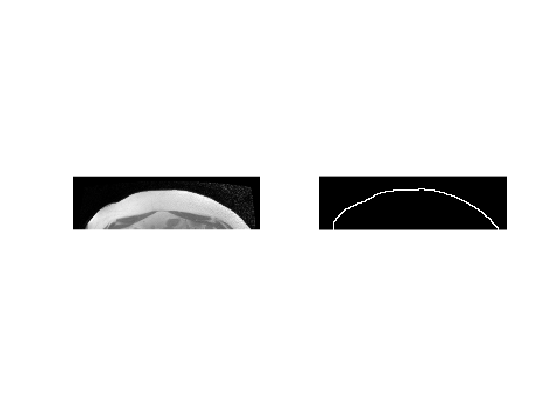


figure();
subplot(1, 2, 1), imshow(data2.testImage, []);
subplot(1, 2, 2), imshow(data2.testSegmentation, []);

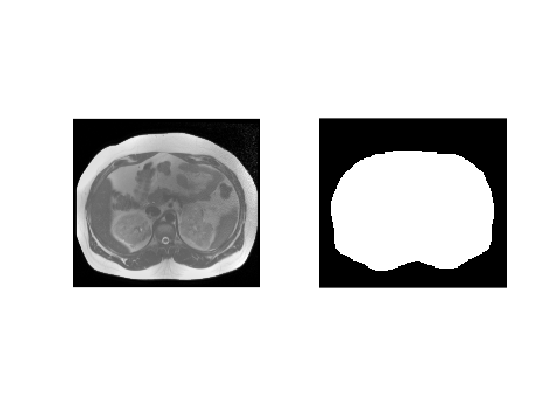


figure();
subplot(1, 2, 1), imshow(data3.trainingImage, []);
subplot(1, 2, 2), imshow(data3.trainingSegmentation, []);

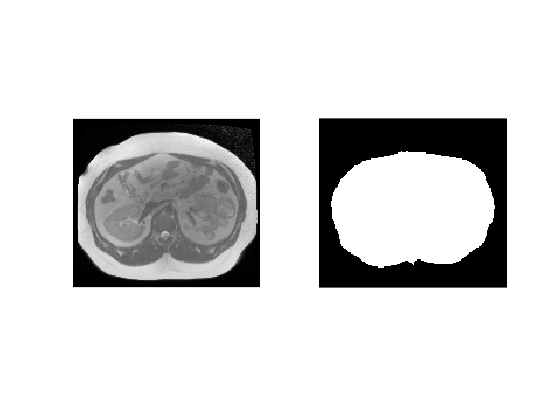


figure();
subplot(1, 2, 1), imshow(data3.testImage, []);
subplot(1, 2, 2), imshow(data3.testSegmentation, []);

%Define Beta vector, cost vectors, stepsize and the training/testing image
maxIter = 5000;
M = 6;
Beta = zeros([1, 6]);
ImTrain = data3.trainingImage;
ImTrainSegm = data3.trainingSegmentation;
ImTest = data3.testImage;
ImTestSegm = data3.testSegmentation;
stepSize = 0.005;
costVectorTrain = zeros([1 maxIter]);
costVectorTest = zeros([1 maxIter]);


for k = 1:maxIter
    randSamp = randperm(length(ImTrain(:)), 200);
    ImTrainRes = zeros(size(ImTrain));
    ImTestRes = zeros(size(ImTest));
    for j = 1:M
        ImTrainRes = ImTrainRes + Beta(j) * BasisFun(ImTrain, j);
        ImTestRes = ImTestRes + Beta(j) * BasisFun(ImTest, j);
    end
    ImTrainRes = Sigmoid(ImTrainRes);
    ImTestRes = Sigmoid(ImTestRes);
    costVectorTrain(k) = getCost(ImTrainRes, ImTrainSegm, randSamp);
    costVectorTest(k) = getCost(ImTestRes, ImTestSegm, randSamp);
    delta = 0.001;
    Gradient = zeros(size(Beta));
    for i = 1:length(Beta)
        newBeta = Beta;
        newBeta(i) = newBeta(i) + delta;
        ImTrainRes = zeros(size(ImTrain));
        for j = 1:M
            ImTrainRes = ImTrainRes + newBeta(j) * BasisFun(ImTrain, j);
        end
        ImTrainRes = Sigmoid(ImTrainRes);
        newCost = getCost(ImTrainRes, ImTrainSegm, randSamp);
        Gradient(i) = (newCost - costVectorTrain(k)) / delta;
    end
    Beta = Beta - stepSize * Gradient;
end
ImTrainRes = zeros(size(ImTrain));
for i = 1:6
    ImTrainRes = ImTrainRes + Beta(i) * BasisFun(ImTrain, i);
end
ImTrainRes = Sigmoid(ImTrainRes);

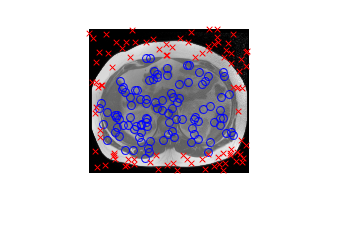

%Obtain indices of the 200 random points from the last iteration where the segmentation is 1/0
randSampTrue = randSamp(ImTrainSegm(randSamp) == 1);
randSampFalse = randSamp(ImTrainSegm(randSamp) == 0);
%Plot the points on the image
figure();
imshow(data3.trainingImage)
hold on;
plot(idivide(int16(randSampTrue), size(data3.trainingImage, 1)), ...
    mod(randSampTrue, size(data3.trainingImage, 1)), 'ob')
plot(idivide(int16(randSampFalse), size(data3.trainingImage, 1)), ...
    mod(randSampFalse, size(data3.trainingImage, 1)), 'xr')

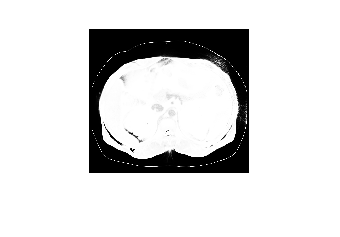

%Plot the posterior of the training image
figure();
imshow(ImTrainRes)

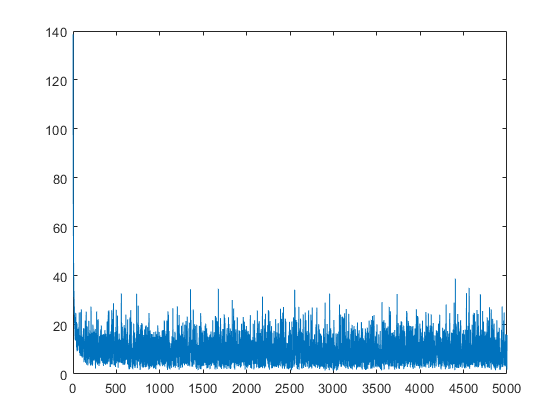

%Plot the progression of the cost vector throughout the iterations
figure();
plot(costVectorTrain);

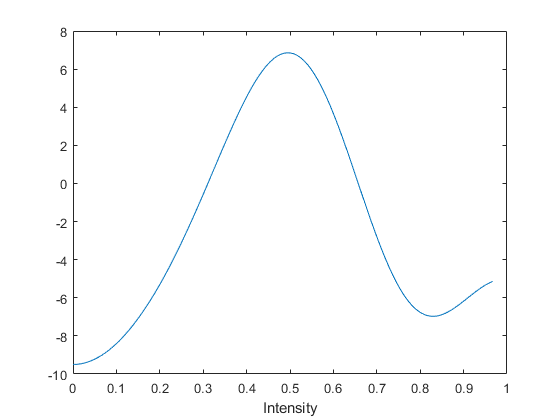

% hold on;
% plot(costVectorTest);
% hold off;
% legend("Training dataset", "Testing dataset")
%Plot the value of a = sum(beta * basisFunction) across the intensity
%values
X = 0:0.001:max(ImTrain(:));
Y = Beta(1) * BasisFun(X, 1);
for i = 2:6
    Y = Y + Beta(i) * BasisFun(X, i);
end
figure();
plot(X,Y)
xlabel("Intensity")

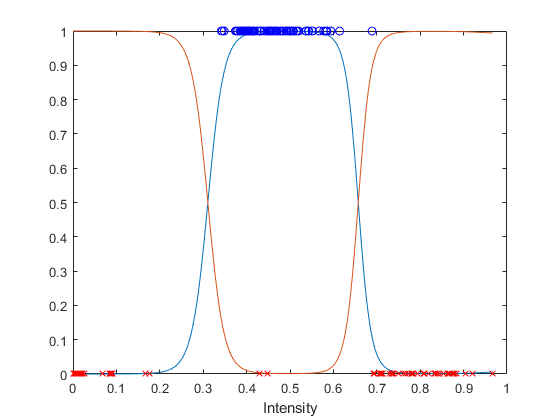

figure();
%Plot the squashed sigma(a) and add the selected points from the previous
%iteration
plot(X, Sigmoid(Y))
hold on;
plot(X, 1 - Sigmoid(Y))
plot(ImTrain(randSampTrue), 1, 'ob')
plot(ImTrain(randSampFalse), 0, 'xr')
xlabel("Intensity")
hold off;

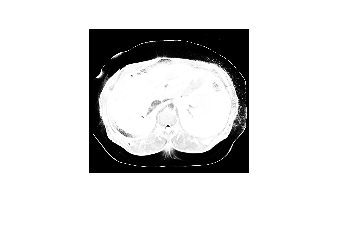

%Apply the model to the test image
ImTest = data3.testImage;
ImTestRes = zeros(size(ImTest));
for i = 1:6
    ImTestRes = ImTestRes + Beta(i) * BasisFun(ImTest, i);
end
ImTestRes = Sigmoid(ImTestRes);
imshow(ImTestRes)

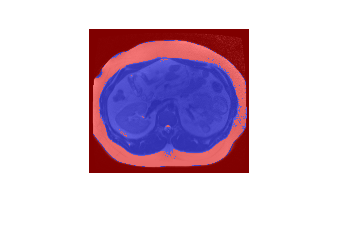

Blue = (ImTestRes > 0.5);
Red = (ImTestRes <= 0.5);
rgb = zeros(size(ImTest));
rgb(:, :, 1) = Red;
rgb(:, :, 3) = Blue;
imshowpair(ImTest, rgb, 'blend')

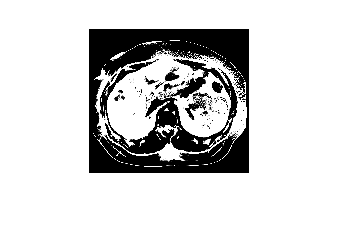

%Replace the test image with a new one with d=d^1.3 
ImTestNew = ImTest.^1.3;
figure();
subplot(1, 2, 1), imshow(ImTest), title("Original test image");
subplot(1, 2, 2), imshow(ImTestNew), title("Modified test image");
ImTestNewRes = zeros(size(ImTestNew));
for i = 1:6
    ImTestNewRes = ImTestNewRes + Beta(i) * BasisFun(ImTestNew, i);
end
figure();
imshow(ImTestNewRes)

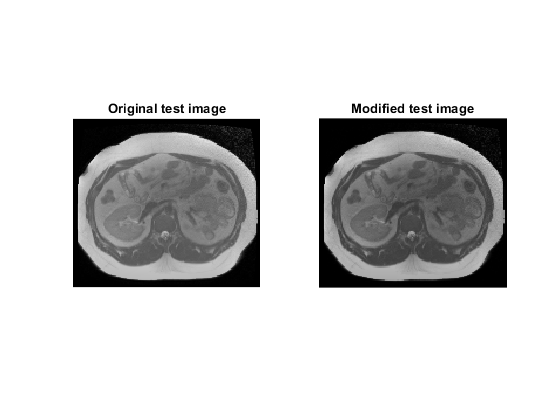

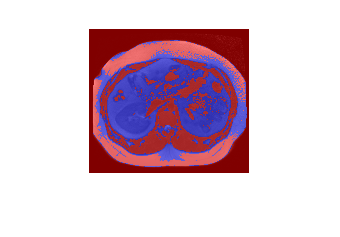

rgb(:, :, 1) = ImTestNewRes <= 0.5;
rgb(:, :, 3) = ImTestNewRes > 0.5;
figure();
imshowpair(ImTestNew, rgb, 'blend');

%Apply the neural network with adaptive basis functions applied on a single
%point
M = 6;
p = 1;
maxIter = 5000;
stepSize = 0.005;
N = 200;
ImTrain = data3.trainingImage;
ImTrainSegm = data3.trainingSegmentation;
ImTest = data3.testImage;
ImTestSegm = data3.testSegmentation;
[Beta, weights, costVectorTrain, costVectorTest, randSamp] = ...
    StochGradDescentAdBasFun(ImTrain, ImTrainSegm, ImTest, ImTestSegm, ...
    M, p, stepSize, N, maxIter);


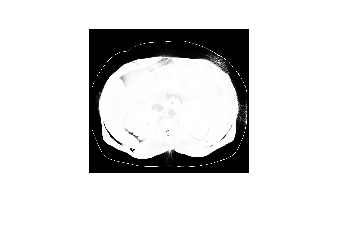

%Visualize the results and obtain the cost at the last iteration
ImTrainRes = zeros(size(ImTrain));
for i = 1:M
    ImTrainRes = ImTrainRes + Beta(i) * AdBasisFun(ImTrain, weights, i, p);
end
ImTrainRes = Sigmoid(ImTrainRes);
%Show the segmentation of the training image
figure();
imshow(ImTrainRes)

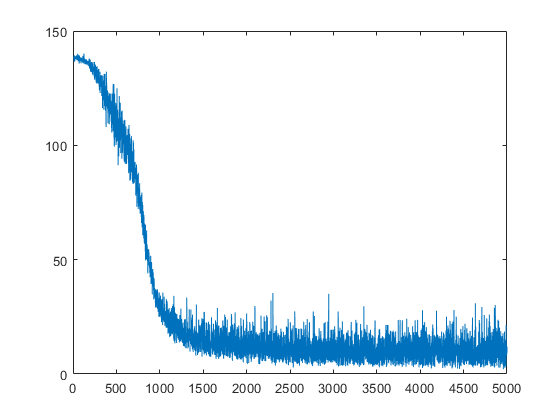

%Plot the evolution of the cost
figure();
plot(costVectorTrain)

%Show the cost at the last iteration
disp("The value of the cross entropy in the final iteration:")

The value of the cross entropy in the final iteration:


costVectorTrain(end)

ans = 11.9290

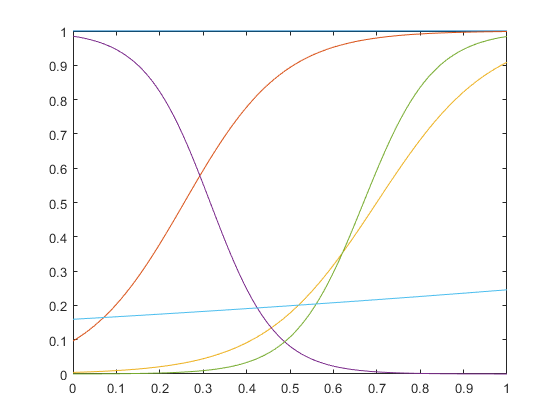

%Visualize the basis functions
figure();
X = linspace(0, 1, 100);


for i = 1:M
    plot(X, AdBasisFun(X, weights, i, 1));
    hold on;
end
hold off;

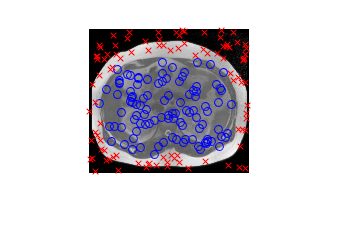

%Visualize the last iteration sample on the image
randSampTrue = randSamp(ImTrainSegm(randSamp) == 1);
randSampFalse = randSamp(ImTrainSegm(randSamp) == 0);
figure();
imshow(data3.trainingImage)
hold on;
plot(idivide(int16(randSampTrue), size(data3.trainingImage, 1)),...
    mod(randSampTrue, size(data3.trainingImage, 1)), 'ob')
plot(idivide(int16(randSampFalse), size(data3.trainingImage, 1)),...
    mod(randSampFalse, size(data3.trainingImage, 1)), 'xr')
hold off;

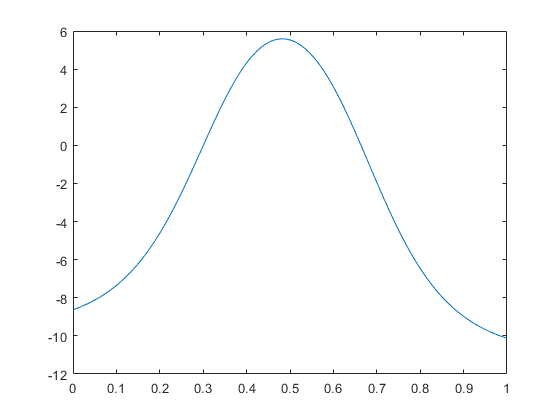

%Visualize the activation function
Y = zeros([1, length(X)]);
for i = 1:M
    Y = Y + Beta(i) * AdBasisFun(X, weights, i, 1);
end
figure();
plot(X, Y)

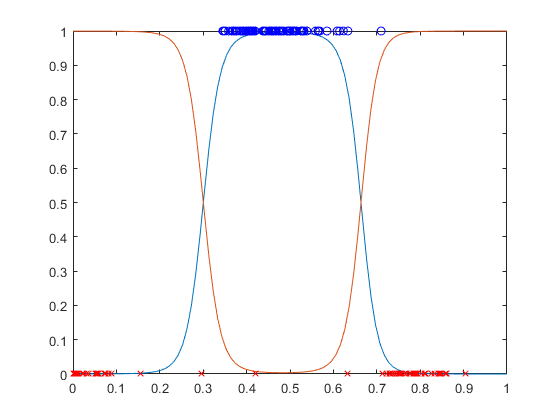

figure();
plot(X, Sigmoid(Y))
hold on;
plot(X, 1 - Sigmoid(Y));
plot(ImTrain(randSampTrue), 1, 'ob')
plot(ImTrain(randSampFalse), 0, 'xr')
hold off

%Apply the neural network with adaptive basis functions applied on a point
%and its neighbour 1 row below
M = 6;
p = 2;
maxIter = 5000;
stepSize = 0.005;
N = 200;
ImTrain = data2.trainingImage;
ImTrainSegm = data2.trainingSegmentation;
ImTest = data2.testImage;
ImTestSegm = data2.testSegmentation;
%Obtain the parameters using the SGD optimizer
[Beta, weights, costVectorTrain, costVectorTest, randSamp] = ...
    StochGradDescentAdBasFun(ImTrain, ImTrainSegm, ImTest, ImTestSegm, ...
    M, p, stepSize, N, maxIter);

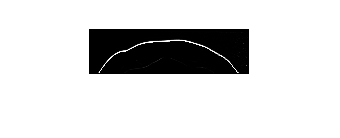

%Visualize the results given the parameters
ImTrainRes = zeros(size(ImTrain));
for i = 1:M
    ImTrainRes = ImTrainRes + Beta(i) * AdBasisFun(ImTrain, weights, i, p);
end
ImTrainRes = Sigmoid(ImTrainRes);
figure();
imshow(ImTrainRes)


%Visualize the evolution of the cross entropy across iterations
figure();
plot(costVectorTrain)
disp("The cross entropy at the last iteration");

The cross entropy at the last iteration


costVectorTrain(end)

ans = 1.8500

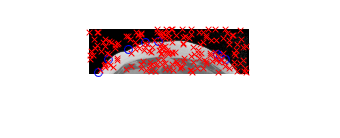


%Visualize the last iteration sample on the image
randSampTrue = randSamp(ImTrainSegm(randSamp) == 1);
randSampFalse = randSamp(ImTrainSegm(randSamp) == 0);
XCoordsTrue = idivide(int16(randSampTrue), size(data2.trainingImage, 1));
YCoordsTrue = mod(randSampTrue, size(data2.trainingImage, 1));
XCoordsFalse = idivide(int16(randSampFalse), size(data2.trainingImage, 1));
YCoordsFalse = mod(randSampFalse, size(data2.trainingImage, 1));
figure();
imshow(data2.trainingImage)
hold on;
plot(XCoordsTrue, YCoordsTrue, 'ob')
plot(XCoordsFalse, YCoordsFalse, 'xr')
hold off;

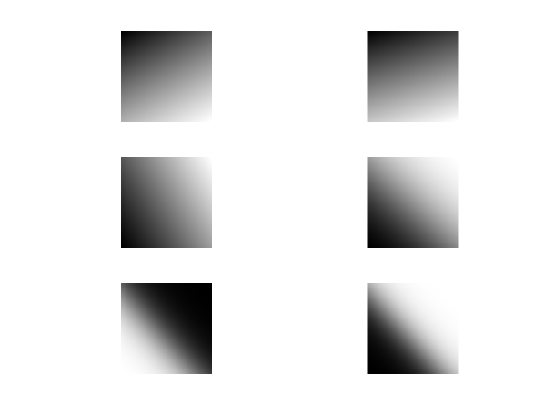


%Visualize the 6 basis functions
X = linspace(0, 1, 100);
[X1, X2] = meshgrid(X);
figure();
for i = 1:M
    Y = Sigmoid(weights(i, 1) + weights(i, 2) * X1 + weights(i, 3) * X2);
    subplot(3, 2, i), imshow(Y, [])
end

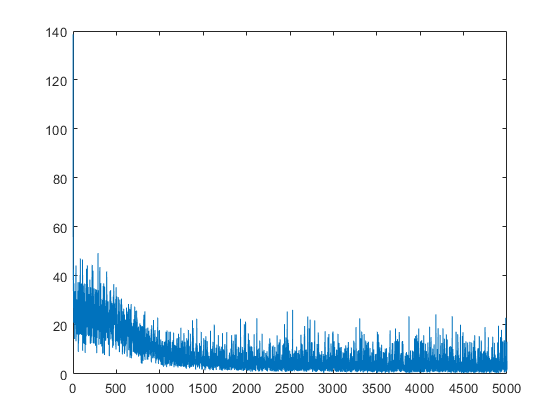


%Visualize the combination of the basis functions
Y = zeros(100);
for i = 1:M
    Y = Y + Beta(i) * Sigmoid(weights(i, 1) + weights(i, 2) * X2 + weights(i, 3) * X1);
end
Y = Sigmoid(Y);
figure();
imshow(Y, []);

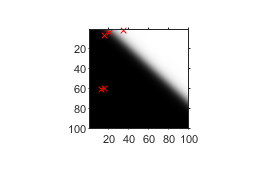

set(gca, 'Visible', 'on')
hold on;
plot(ImTrain(randSampTrue) * 100, ImTrain(randSampTrue + size(ImTrain, 2)) * 100, 'rx')

plot(ImTrain(randSampFalse), ImTrain(randSampFalse + size(ImTrain, 2)), 'xr')

Index exceeds the number of array elements (7200).

length(ImTrain(:))

ans = 7200

45*160

ans = 7200

%Some testing section
weights

weights =    -0.2281    0.4103    0.7797
    1.0633    0.0224    0.0737
   -0.5032    1.4054   -0.8370
    0.4497    2.8025   -3.0758
   -0.5869   -5.9884    5.3549
    0.7015    6.6098   -6.0800


weights(5) = weights(5) + delta

weights =    -0.2281    0.4103    0.7797
    1.0633    0.0224    0.0737
   -0.5032    1.4054   -0.8370
    0.4497    2.8025   -3.0758
   -0.5859   -5.9884    5.3549
    0.7015    6.6098   -6.0800


a = [1 2; 3 4]

a =      1     2
     3     4


imfilter(a, [1 1])

ans =      3     2
     7     4


rng(1405)
normrnd(0, 1)

ans = -0.3091